# Tarea_01_Funciones

## Señales en tiempo discreto:

- X(n) = Aδ(n-n0)

- X(n) = Au(n-n0)

- X(n) = A(n-n0)*u(n-n0)

- X(n)=a^n u(n)

- X(n)=A*sen(wn)/wn

- X(n)=chirp

## Datos:

prompt_01 = 'Ingresa el valor del dominio Inicial:  ';
prompt_02 = 'Ingresa el valor del dominio Final:   ';
prompt_03 = 'Ingresa el valor de la amplitud:   ';
Dominio_Incial = input(prompt_01);
Dominio_Final = input(prompt_02);
Amplitud = input(prompt_03);
x = Dominio_Incial:abs(Dominio_Final-Dominio_Incial)/100:Dominio_Final;
n=Dominio_Incial:Dominio_Final;
size(x);


## Impulso de dirac:

a delta de Dirac no es una función estrictamente hablando, puesto que se puede ver que requeriría tomar valores infinitos. A veces, informalmente, se expresa la delta de Dirac como el límite de una sucesión de funciones que tiende a cero en todo punto del espacio excepto en un punto para el cual divergiría hacia infinito; de ahí la "expresión informal" como función definida a trozos.


a=1/Amplitud

a = 0.2000

impulso = (1/(abs(a)*sqrt(pi)))*exp(-(n/a).^2)

impulso =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    2.8209    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


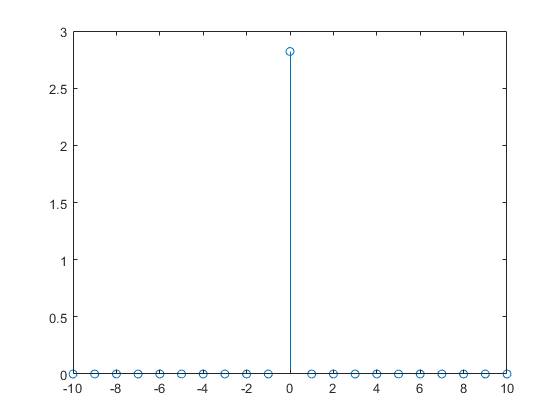

stem(n,impulso)

## Escalon unitario:

La **función escalón de Heaviside**, también llamada **función escalón unitario** o **de causalidad a la derecha del cero**, debe su nombre al matemático inglés Olive heaviside. Es una función discontinua cuyo valor es 0 para cualquier argumento negativo, y 1 para cualquier argumento positivo, incluido el cero.

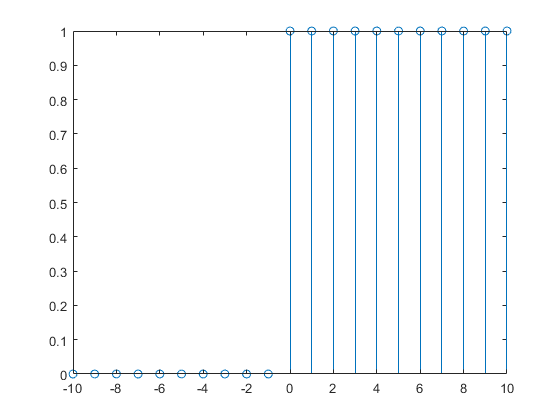

escalon= 1*[zeros(1,abs(Dominio_Incial))  ones(1, abs(Dominio_Final)+1)  ]; 
stem(n,escalon)

## Señal rampa

La **función rampa** es una función elemental real de un solo argumento, continua y diferenciable en todo su dominio excepto en un punto (inicio de la rama) fácilmente computable a partir de la función mínimo o la función valor absoluto.

Las principales aplicaciones prácticas de esta función se dan en ingeniería (procesamiento digital de señales, plasticidad, etc.). El término "función rampa" se debe a la forma de su representación gráfica.

rampa =  Amplitud*n

rampa =    -50   -45   -40   -35   -30   -25   -20   -15   -10    -5     0     5    10    15    20    25    30    35    40    45    50


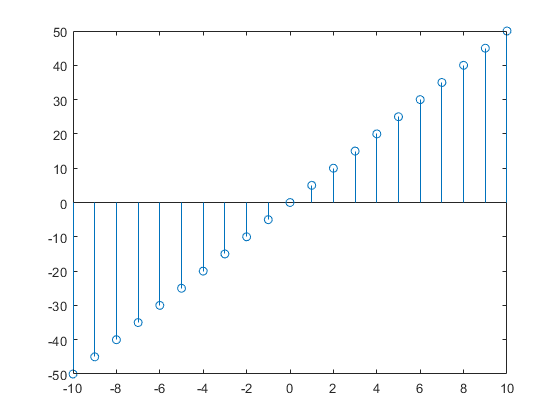

stem(n,rampa)

## Señal Exponencial 

**Señales Exponenciales Reales:**

- ***A*** Real, ***a*** <> 0,  ***b*** = 0

- Una expresión más general de ***x******[n]*** sería: ***x[n]*** = ***c******n*** , donde  ***c*** = ***(e*** ***a******)***

- Si ***a*** > 0 (***c*** > 1), entonces  ***x******[n]*** es una exponencial creciente.

- Si ***a*** < 0 (***c*** < 1), entonces  ***x******[n]*** es una exponencial decreciente.

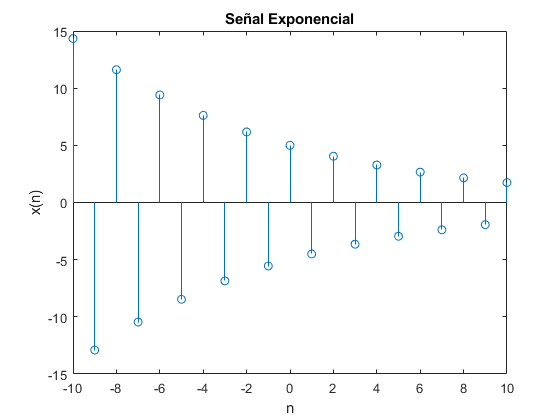


a=-0.9; % Base real 


x= Amplitud*a.^n;

stem(n,x); xlabel('n'); ylabel('x(n)'); title('Señal Exponencial');

**Señales Exponenciales Complejas:**

- ***A*** Real, ***a*** = 0,  ***b*** <> 0

- Esta señal, es periódica con período **N** si NB=2πm, siendo **N** y **m** enteros, en caso contrario la señal es aperiódica.

Usando la relación de Euler se puede escribir en términos de señales senoidales:

***x[n]***** = ACos( b n ) + j ASen( b n )**

b=0.9+1i*0.8; %Base complej

x= A*b.^n;

Undefined function or variable 'A'.


x_real= real(x);
x_imaginario= imag(x);
x_magnitud= abs(x);
x_angulo= angle(x);

figure
subplot(2,2,1);
stem(n,x_real); xlabel('n'); ylabel('x(n) Real'); title('Señal Exponencial Compleja');grid on

subplot(2,2,2);
stem(n,x_imaginario); xlabel('n'); ylabel('x(n) Imaginario'); title('Señal Exponencial Compleja');grid on

subplot(2,2,3);
stem(n,x_magnitud); xlabel('n'); ylabel('x(n) Mag'); title('Señal Exponencial Compleja');grid on

subplot(2,2,4);
stem(n,x_angulo); xlabel('n'); ylabel('x(n) Angle'); title('Señal Exponencial Compleja');grid on

## Señal senosoidal:

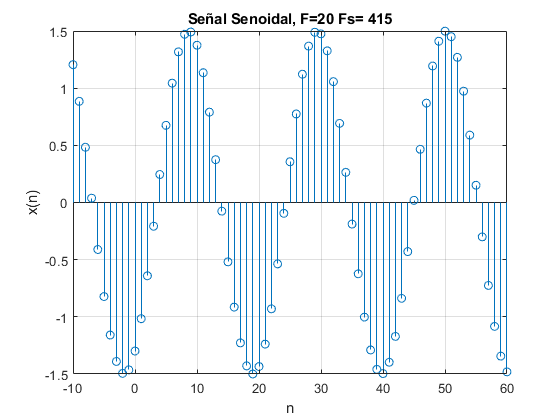

%% Señal Senoidal
A=1.5;
F= 20;   % Frecuencia análoga
Fs=415; % Frecuencia de muestreo
Ts=1/Fs;
ni=-10;
nf=60;
n=ni:nf;
x= A*sin(2*pi*F*n/Fs-(pi/3));

figure
stem(n,x);
xlabel('n'); ylabel('x(n)'); title(['Señal Senoidal, F=' num2str(F) ' Fs= ' num2str(Fs)]);grid on

## Señal chirp:

A **chirp** is a signal in which the frequency increases (*up-chirp*) or decreases (*down-chirp*) with time. In some sources, the term *chirp* is used interchangeably with **sweep signal**.It is commonly used in sonar, radar, and laser, but has other applications, such as in spread-spectrum communications.

time=0:1:40;
omega= 2

omega = 2

M = 10

M = 10

A= 10

A = 10

s_t = time.^2/4

s_t =          0    0.2500    1.0000    2.2500    4.0000    6.2500    9.0000   12.2500   16.0000   20.2500   25.0000   30.2500   36.0000   42.2500   49.0000   56.2500   64.0000   72.2500   81.0000   90.2500  100.0000  110.2500  121.0000  132.2500  144.0000  156.2500  169.0000  182.2500  196.0000  210.2500  225.0000  240.2500  256.0000  272.2500  289.0000  306.2500  324.0000  342.2500  361.0000  380.2500  400.0000


chirp_man=A*cos(omega*time+s_t)

chirp_man =    10.0000   -6.2817    2.8366   -3.8575    8.4385   -8.5666   -5.4773    4.3815    8.3422    8.5206    5.2532   -4.0202   -9.5241    6.4861   -0.3098   -1.4330   -1.8043    8.4504   -7.2410   -8.4974   -1.9781    1.1698   -0.6634   -6.8165   -9.3489    4.5794    4.6380   -8.0770    7.8221   -3.4869   -6.3334    7.9176    9.0371    5.0449    4.1617    7.3771    9.8733    0.1103   -9.4967    9.1206   -7.8773


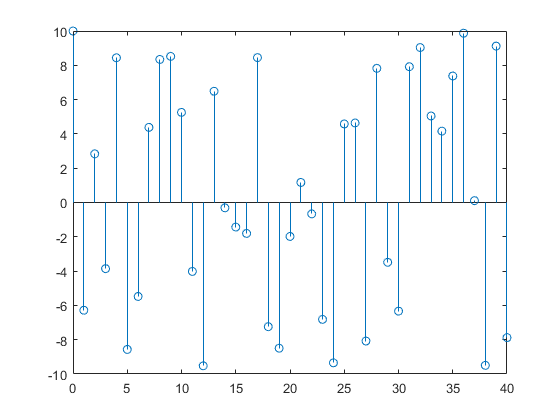

stem(time,chirp_man)


% double Chirp(double w1, double w2, double A, double M, double time)
%    {
%    double res;
%    res=A*cos(w1*time+(w2-w1)*time*time/(2*M));
%    return res;
%    }